clc; clear; close all;
tic

## 读取数据

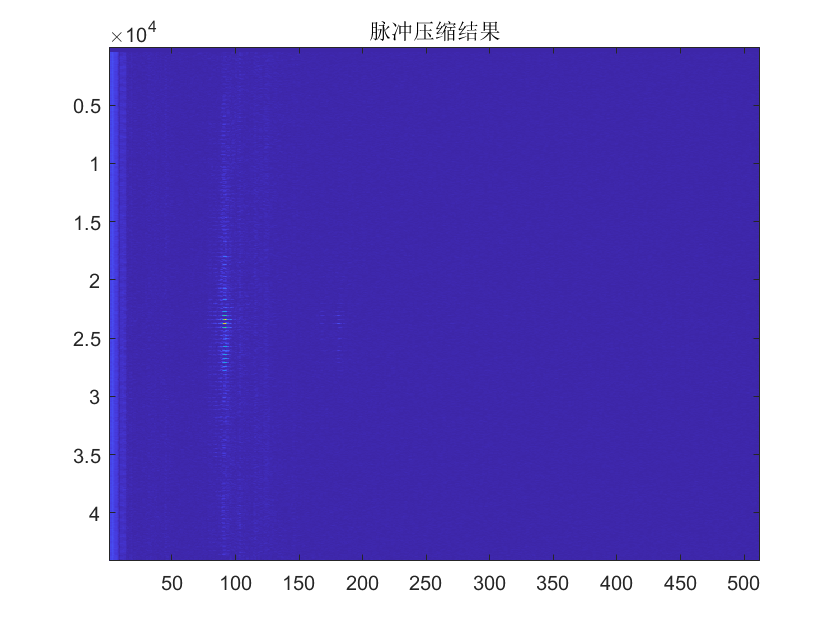

fft_R = 512;
fft_ratio = 1;
Radar = load("2024_08_26_195902_133527.mat").Radar;
Echo0 = Radar.data;
Echo0 = fft(conj(Echo0), fft_R*2, 2);
Echo0 = Echo0(1:end,1:fft_R);
figure; imagesc(abs(Echo0)); title('脉冲压缩结果');

% Echocorr = corrcoef(Echo0(64857:65000,:).');
% figure; imagesc(abs(Echocorr)); title('行间互相关');

## 扫描行标定

% Echo_move0 = Echo0(1:64857-1+89,:);
Echo_move0 = Echo0;
ID_range = 40:90;
% ID_range = 69:74;

% max_ID0 = Echo_move(:,ID_select);
% figure; plot(abs(max_ID0)); title('指定距离门强度变化');
% max_ID = max_ID0(12100:18187);
% [pks,locs] = findpeaks(abs(max_ID),'MinPeakDistance',270,'MinPeakProminence',10000);
% figure; findpeaks(abs(max_ID),'MinPeakDistance',270,'MinPeakProminence',10000);
% % locs(1:4) = [];
% figure; yyaxis left; plot(locs); hold on; yyaxis right; plot(diff(locs)); title('最强点位置');
% ave_NX = sum(diff(locs))/(length(locs)-1)
% mod_idx = mod(locs,ave_NX);
% figure; plot(mod_idx); title('最强点模平均一行扫描行数');
% ave_mod_idx = sum(mod_idx)/length(mod_idx)

## 全部位置计算

% max_ID = max_ID0;
% [pks,locs] = findpeaks(abs(max_ID),'MinPeakDistance',270,'MinPeakProminence',10000);
% figure; findpeaks(abs(max_ID),'MinPeakDistance',270,'MinPeakProminence',10000);
% locs_dis = diff(locs);
% locs_dis(locs_dis>400) = [];
% locs_dis = locs_dis(20:160)
% figure; plot(locs_dis); title('最强点位置');
% ave_NX = sum(locs_dis)/(length(locs_dis))

## 确定雷达航迹数据

% Echo_move = [zeros(0,512);Echo_move0];
Echo_move = [zeros(0,fft_R);Echo0(700:end,:)];
Nx = 336;   %322-325-332             % The sampling points in the horizontal direction
Nz = 128;                            % The sampling points in the vertical direction
Echo = zeros(Nx*Nz,fft_R);      % Echo of 1T1R
err = 12;                            % Number of movement error points
for ii = 1 : Nz
    kk = fix(ii/Nz*err);
%     kk = 0;
    Echo((ii-1)*Nx+1:ii*Nx,:) = Echo_move((ii-1)*Nx+1+kk:ii*Nx+kk,:);
end
Echo = reshape(Echo,[Nx,Nz,fft_R]);

## 系统参数

dx0 = 400/Nx;                               % Sampling distance at x (horizontal) axis in mm
dy0 = 2;                               % Sampling distance at y (vertical) axis in mm
interp_factor = 1;
dx = sqrt(dx0^2+(dy0/437)^2)/interp_factor; dy = dy0/interp_factor;
nFFTspace = 1024*interp_factor;                      % Number of FFT points for Spatial-FFT
c = physconst('lightspeed');
F0 = 121*1e9;
B = 10*1e9;
Fs = Radar.fs_MHz*1e6;                % Sampling rate (sps)
Ts = 1/Fs;                            % Sampling period
Tp = 315*1e-6;
Kf = B/Tp;                        % Slope const (Hz/sec)
tI = 0;                      % Instrument delay for range calibration
k = 2*pi*F0/c;
fft2mm = Fs*c/fft_R/2/Kf*1000

fft2mm = 8.2999

## RMA成像

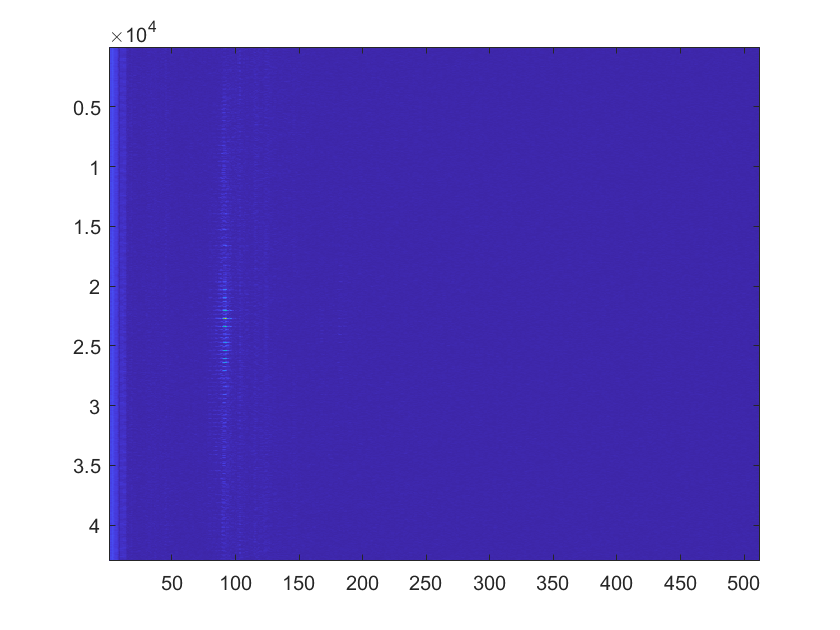

nFFTtime = 512*fft_ratio;
% Sr = fft(Echo,nFFTtime,3);                               % Range FFT
Sr = Echo;
figure;imagesc(abs(reshape(Sr,[],nFFTtime)));

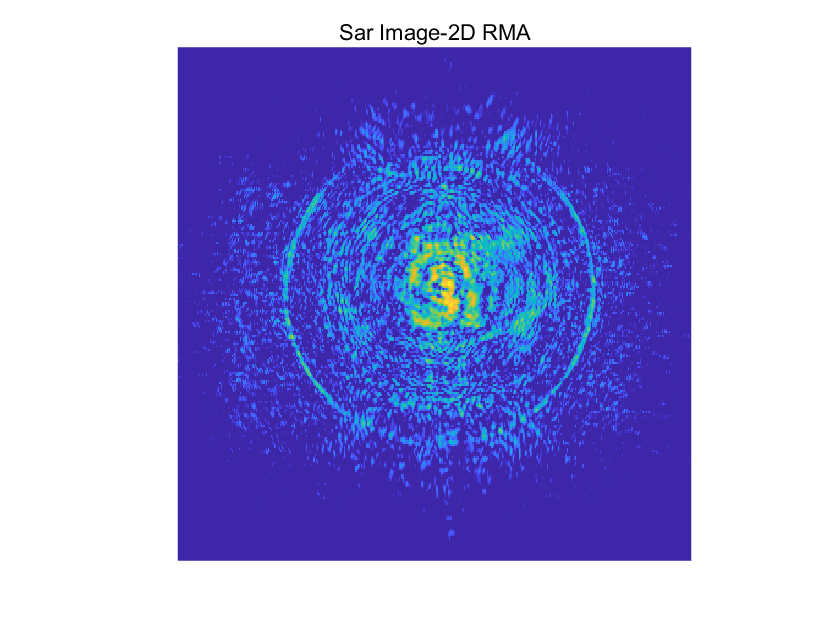

imSize = 500;                                            % Size of 2D image area in mm
yPointT = nFFTspace;
xPointT = nFFTspace;

xRangeT = dx * (-(xPointT-1)/2 : (xPointT-1)/2);
yRangeT = dy * (-(yPointT-1)/2 : (yPointT-1)/2);
indXpartT = xRangeT>(-imSize/2) & xRangeT<(imSize/2);
indYpartT = yRangeT>(-imSize/2) & yRangeT<(imSize/2);
xRangeT = xRangeT(indXpartT);
yRangeT = yRangeT(indYpartT);
sarImage_2DFFT = zeros(length(yRangeT),length(xRangeT),length(ID_range));
for ID_select_num = 1:length(ID_range)
    ID_select = ID_range(ID_select_num);
    sarData = squeeze(Sr(:,:,ID_select)).';                  % Selecting echo data after pulse compression
%     sarData = zeros(fix(0.5*size(sarData0)));
%     sarData(1:end,1:end) = sarData0(1:2:end,1:2:end);
    R = c/2*(ID_select/(Kf*Ts*nFFTtime) - tI);
    
    sarData(2:2:end,:) = fliplr(sarData(2:2:end,:));
%     figure; imagesc(abs(sarData));
    wSx = 2*pi/(dx*1e-3);                                    % Sampling frequency for Target Domain
    kX = linspace(-(wSx/2),(wSx/2),nFFTspace);               % kX-Domain
    wSy = 2*pi/(dy*1e-3);                                    % Sampling frequency for Target Domain
    kY = (linspace(-(wSy/2),(wSy/2),nFFTspace)).';           % kY-Domain
    K = single(sqrt((2*k).^2 - kX.^2 - kY.^2));
    phaseFactor0 = exp(-1i*R*K);
    phaseFactor0((kX.^2 + kY.^2) > (2*k).^2) = 0;
    phaseFactor = K.*phaseFactor0;
    phaseFactor = fftshift(fftshift(phaseFactor,1),2);
    % Padding matrix with 0
    [yPointM,xPointM] = size(sarData);
    [yPointF,xPointF] = size(phaseFactor);
    if (xPointF > xPointM)
        sarData = padarray(sarData,[0 floor((xPointF-xPointM)/2)],0,'pre');
        sarData = padarray(sarData,[0 ceil((xPointF-xPointM)/2)],0,'post');
    else
        phaseFactor = padarray(phaseFactor,[0 floor((xPointM-xPointF)/2)],0,'pre');
        phaseFactor = padarray(phaseFactor,[0 ceil((xPointM-xPointF)/2)],0,'post');
    end
    
    if (yPointF > yPointM)
        sarData = padarray(sarData,[floor((yPointF-yPointM)/2) 0],0,'pre');
        sarData = padarray(sarData,[ceil((yPointF-yPointM)/2) 0],0,'post');
    else
        phaseFactor = padarray(phaseFactor,[floor((yPointM-yPointF)/2) 0],0,'pre');
        phaseFactor = padarray(phaseFactor,[ceil((yPointM-yPointF)/2) 0],0,'post');
    end
    
    sarDataFFT = fft2(sarData,nFFTspace,nFFTspace);
    sarImage_2DRMA = ifft2(sarDataFFT.*phaseFactor);
    sarImage_2DFFT(:,:,ID_select_num) = (sarImage_2DRMA(indYpartT,indXpartT));
end
sarImage_2DFFT1 = abs(sum(sarImage_2DFFT,3));
figure;imagesc(xRangeT,yRangeT,db(sarImage_2DFFT1/max(sarImage_2DFFT1(:))),[-20,0]);
axis equal xy off;
title 'Sar Image-2D RMA'

toc

历时 5.011655 秒。


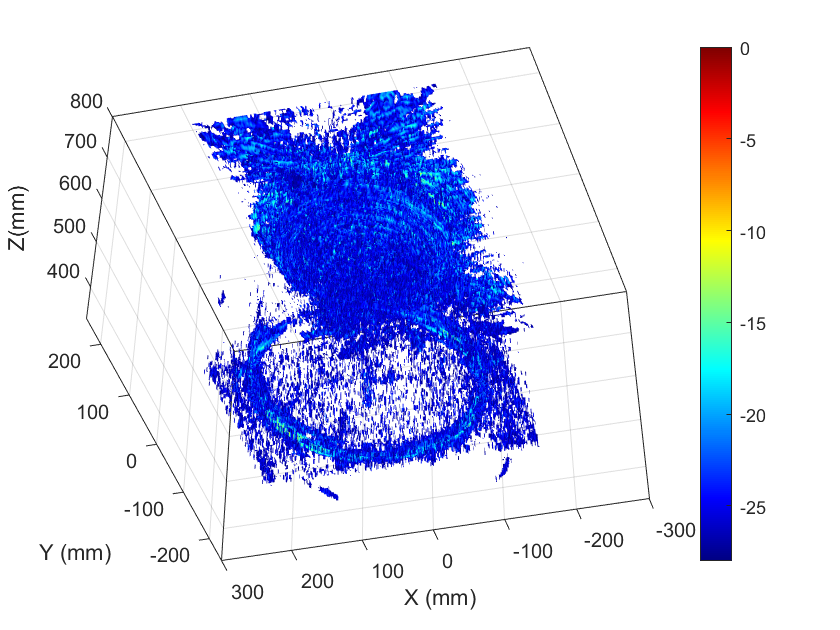

x = xRangeT;
y = yRangeT;
z = fft2mm * ID_range;
[X,Y,Z] = meshgrid(x,y,z);
figure;
img=db(abs(sarImage_2DFFT))-db(max(abs(sarImage_2DFFT(:))));
img(find((img) < -28))=nan;
h=slice(X,Y,Z,(img),x,y,z);
set(h,'FaceColor','interp',...
    'EdgeColor','none')
 xlabel('X (mm)'),ylabel('Y (mm)'),zlabel('Z(mm)')
camproj perspective
box on
colormap jet
colorbar

电路板图片

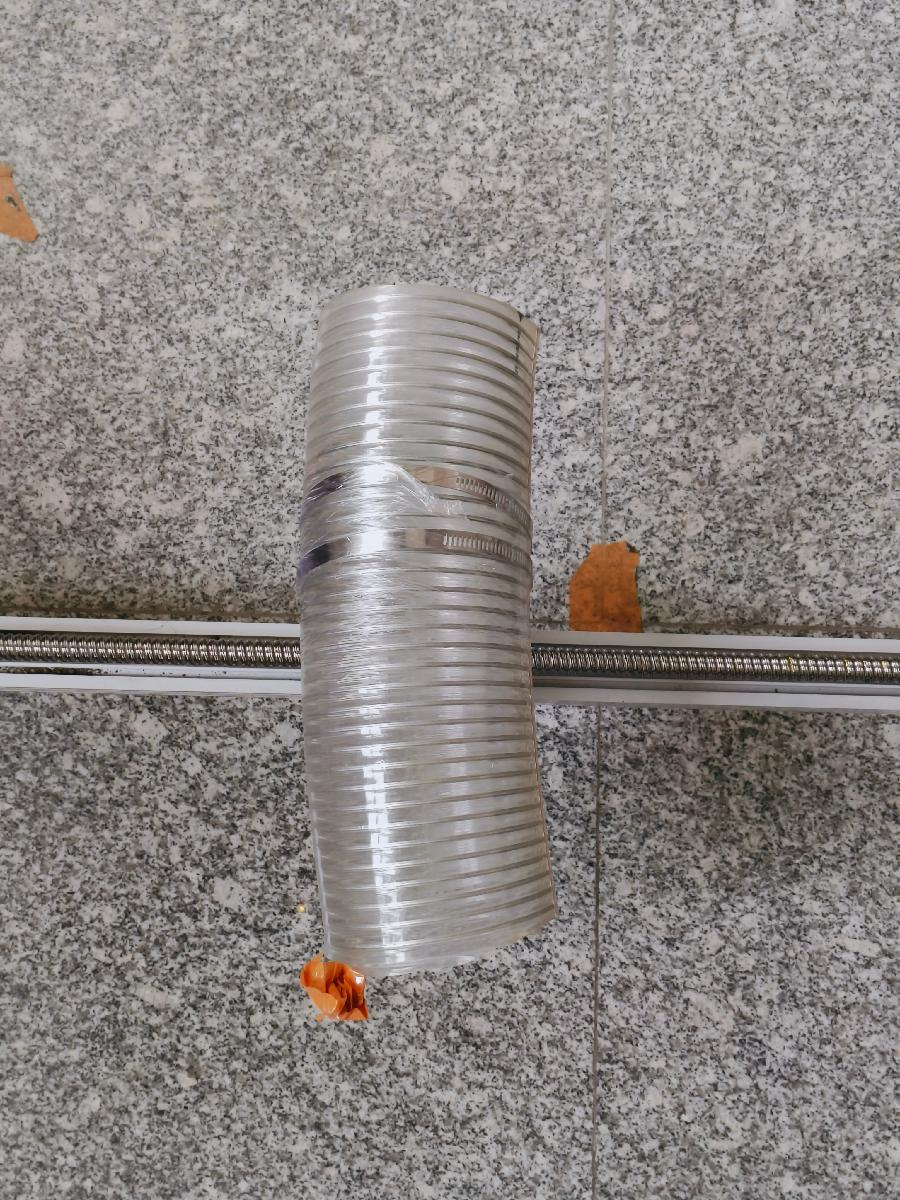

% eval("save " + num2str(ID_select) + ".mat" + " sarImage_2DFFT")